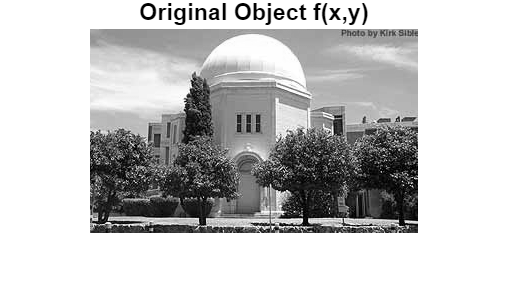

% OPTI 512L
% LAB 6
% Mohanbabu Mani

% Imaging Systems
% 1.


% PSF1 (σ=1.5): High resolution, preserves fine details
% PSF2 (σ=4.0): Medium resolution, moderate blur
% PSF3 (σ=8.0): Low resolution with oscillatory component Creates zeros in OTF at certain spatial frequencies

load forclass; 

figure('Name', 'Original Image', 'Position', [100, 100, 800, 600]);
imshow(img, []);
title('Original Object f(x,y)', 'FontSize', 14, 'FontWeight', 'bold');
colormap(gray);


[M, N] = size(img);
disp(['Image dimensions: ', num2str(M), ' x ', num2str(N)]);

Image dimensions: 204 x 328


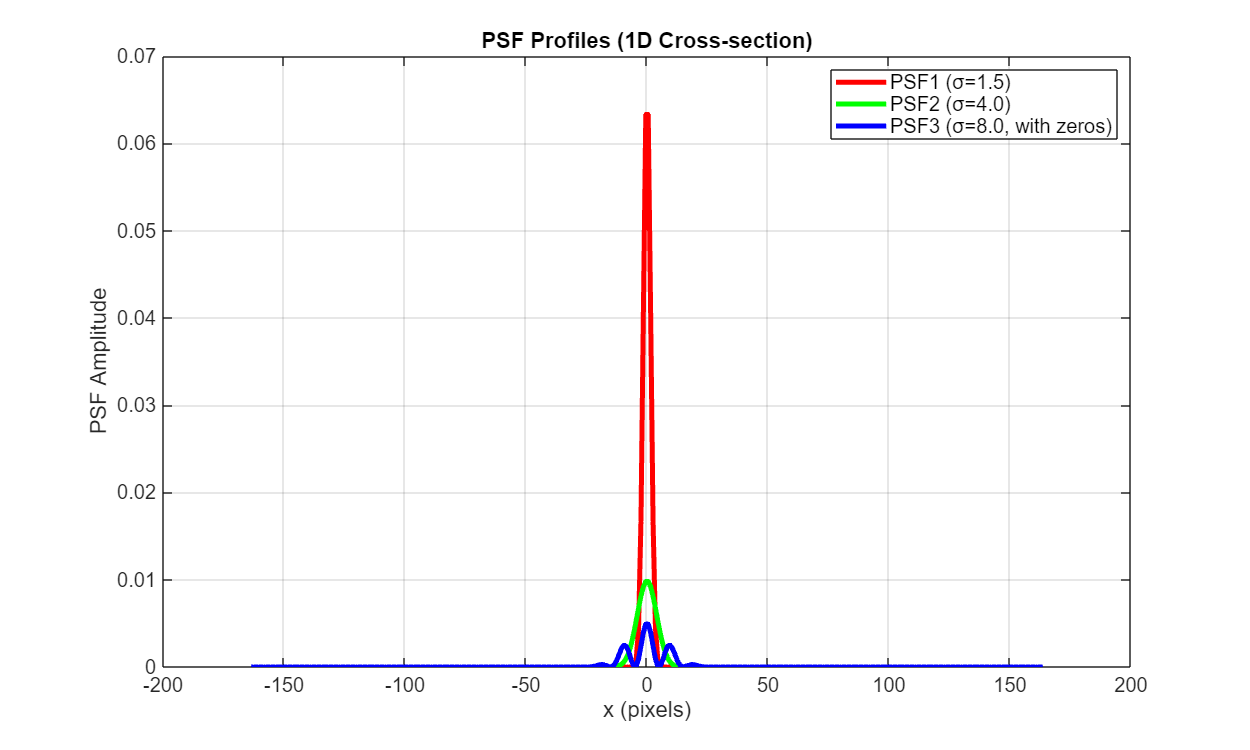


dx = 1; dy = 1; 
x = (-(N-1)/2:(N-1)/2) * dx;
y = (-(M-1)/2:(M-1)/2) * dy;
[X, Y] = meshgrid(x, y);
sigma1 = 1.5;
psf1 = exp(-(X.^2 + Y.^2)/(2*sigma1^2));
psf1 = psf1/sum(psf1(:)); 
sigma2 = 4.0;
psf2 = exp(-(X.^2 + Y.^2)/(2*sigma2^2));
psf2 = psf2/sum(psf2(:)); 
sigma3 = 8.0;
psf3_base = exp(-(X.^2 + Y.^2)/(2*sigma3^2));
k_zero = 0.1; 
oscillation = cos(2*pi*k_zero*sqrt(X.^2 + Y.^2));
psf3 = psf3_base .* (0.5 + 0.5*oscillation);
psf3 = psf3/sum(psf3(:)); 

center_row = ceil(M/2);
center_col = ceil(N/2);

figure('Name', 'PSF Profiles - 1D Cross-sections', 'Position', [200, 200, 1000, 600]);
plot(x, psf1(center_row, :), 'r-', 'LineWidth', 3); hold on;
plot(x, psf2(center_row, :), 'g-', 'LineWidth', 3);
plot(x, psf3(center_row, :), 'b-', 'LineWidth', 3);
title('PSF Profiles (1D Cross-section)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('x (pixels)', 'FontSize', 14);
ylabel('PSF Amplitude', 'FontSize', 14);
legend('PSF1 (σ=1.5)', 'PSF2 (σ=4.0)', 'PSF3 (σ=8.0, with zeros)', 'FontSize', 12, 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 12);

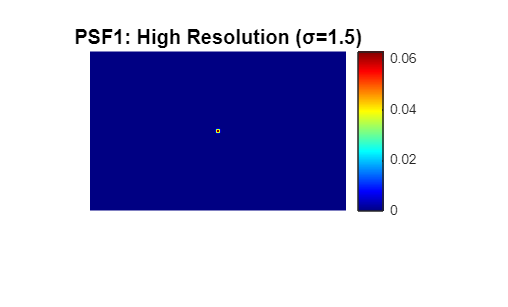



figure('Name', 'PSF1 - High Resolution', 'Position', [300, 300, 600, 500]);
imshow(psf1, []);
title('PSF1: High Resolution (σ=1.5)', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

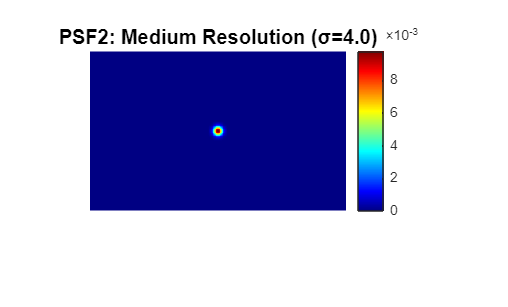


figure('Name', 'PSF2 - Medium Resolution', 'Position', [350, 350, 600, 500]);
imshow(psf2, []);
title('PSF2: Medium Resolution (σ=4.0)', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

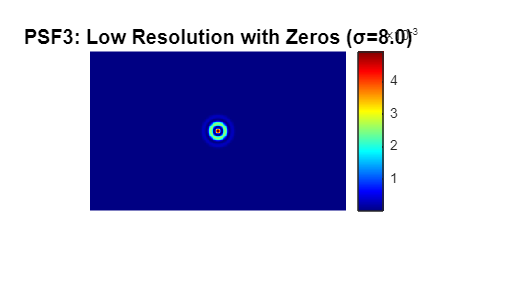


figure('Name', 'PSF3 - Low Resolution with Zeros', 'Position', [400, 400, 600, 500]);
imshow(psf3, []);
title('PSF3: Low Resolution with Zeros (σ=8.0)', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

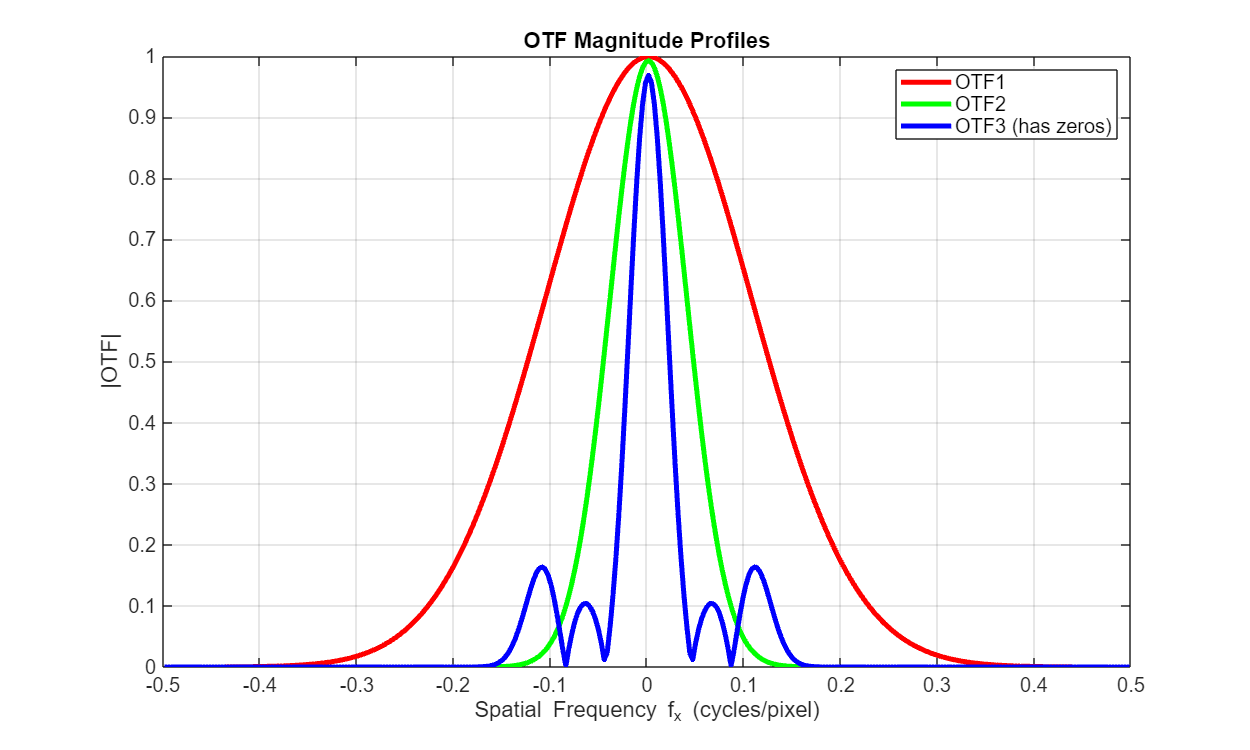


otf1 = fftshift(fft2(ifftshift(psf1)));
otf2 = fftshift(fft2(ifftshift(psf2)));
otf3 = fftshift(fft2(ifftshift(psf3)));

fx = (-(N-1)/2:(N-1)/2) / (N*dx);
fy = (-(M-1)/2:(M-1)/2) / (M*dy);
center_freq_row = ceil(M/2);

figure('Name', 'OTF Magnitude Profiles', 'Position', [450, 450, 1000, 600]);
plot(fx, abs(otf1(center_freq_row, :)), 'r-', 'LineWidth', 3); hold on;
plot(fx, abs(otf2(center_freq_row, :)), 'g-', 'LineWidth', 3);
plot(fx, abs(otf3(center_freq_row, :)), 'b-', 'LineWidth', 3);
title('OTF Magnitude Profiles', 'FontSize', 16, 'FontWeight', 'bold');
xlabel('Spatial Frequency f_x (cycles/pixel)', 'FontSize', 14);
ylabel('|OTF|', 'FontSize', 14);
legend('OTF1', 'OTF2', 'OTF3 (has zeros)', 'FontSize', 12, 'Location', 'northeast');
grid on;
xlim([-0.5, 0.5]);
set(gca, 'FontSize', 12);

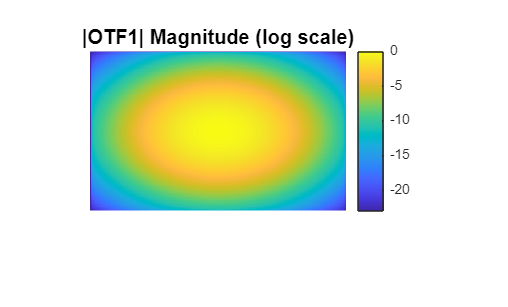


figure('Name', 'OTF1 Magnitude - 2D', 'Position', [500, 500, 600, 500]);
imshow(log(abs(otf1) + 1e-10), []);
title('|OTF1| Magnitude (log scale)', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

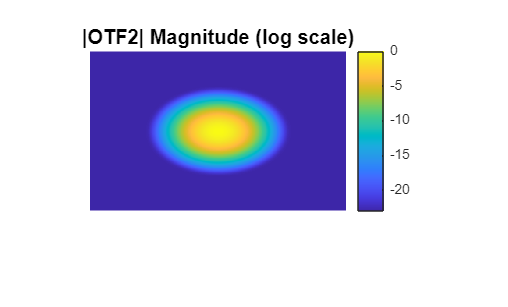


figure('Name', 'OTF2 Magnitude - 2D', 'Position', [550, 550, 600, 500]);
imshow(log(abs(otf2) + 1e-10), []);
title('|OTF2| Magnitude (log scale)', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

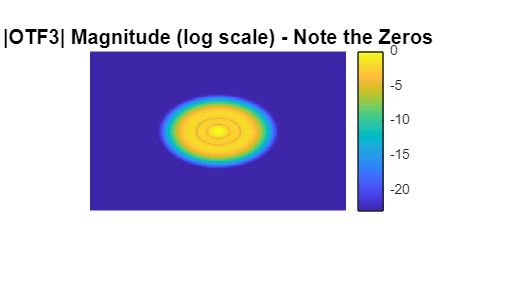


figure('Name', 'OTF3 Magnitude - 2D (Note the Zeros)', 'Position', [600, 600, 600, 500]);
imshow(log(abs(otf3) + 1e-10), []);
title('|OTF3| Magnitude (log scale) - Note the Zeros', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

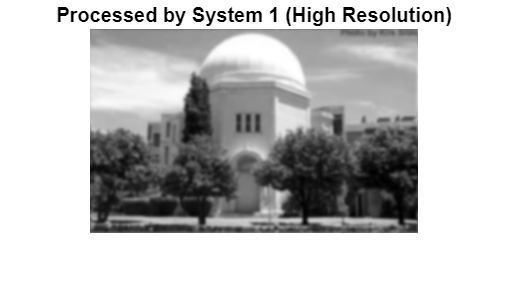


img_fft = fftshift(fft2(img));
img1_fft = img_fft .* otf1;
img2_fft = img_fft .* otf2;
img3_fft = img_fft .* otf3;
img1_processed = real(ifft2(ifftshift(img1_fft)));
img2_processed = real(ifft2(ifftshift(img2_fft)));
img3_processed = real(ifft2(ifftshift(img3_fft)));

figure('Name', 'Processed Image - System 1', 'Position', [650, 650, 600, 500]);
imshow(img1_processed, []);
title('Processed by System 1 (High Resolution)', 'FontSize', 12, 'FontWeight', 'bold');

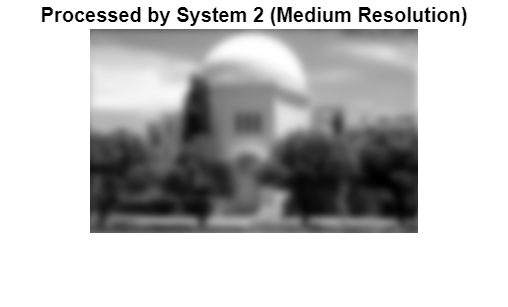


figure('Name', 'Processed Image - System 2', 'Position', [700, 700, 600, 500]);
imshow(img2_processed, []);
title('Processed by System 2 (Medium Resolution)', 'FontSize', 12, 'FontWeight', 'bold');

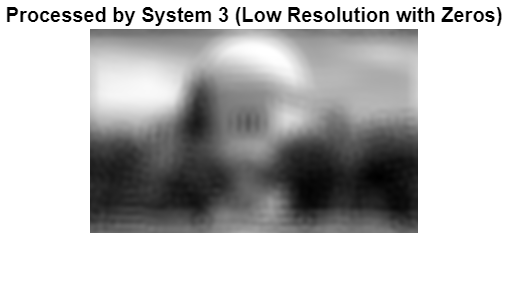


figure('Name', 'Processed Image - System 3', 'Position', [750, 750, 600, 500]);
imshow(img3_processed, []);
title('Processed by System 3 (Low Resolution with Zeros)', 'FontSize', 12, 'FontWeight', 'bold');

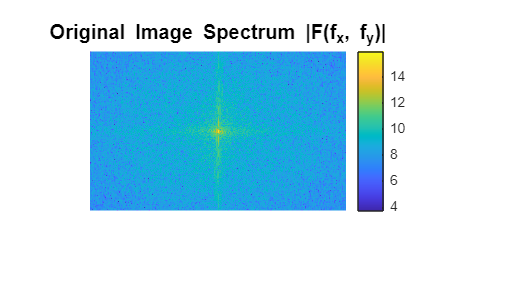


figure('Name', 'Original Image Spectrum', 'Position', [800, 800, 600, 500]);
imshow(log(abs(img_fft) + 1), []);
title('Original Image Spectrum |F(f_x, f_y)|', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

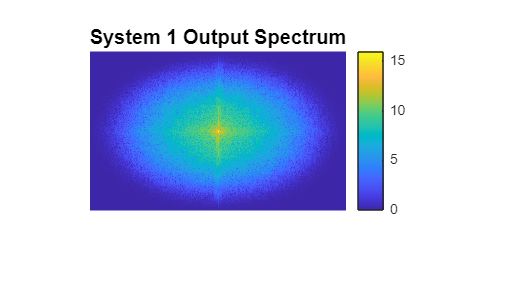


figure('Name', 'System 1 Output Spectrum', 'Position', [850, 850, 600, 500]);
imshow(log(abs(img1_fft) + 1), []);
title('System 1 Output Spectrum', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

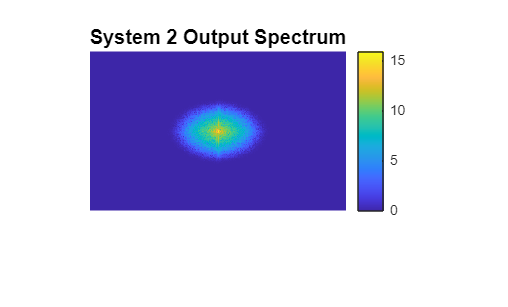


figure('Name', 'System 2 Output Spectrum', 'Position', [900, 900, 600, 500]);
imshow(log(abs(img2_fft) + 1), []);
title('System 2 Output Spectrum', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

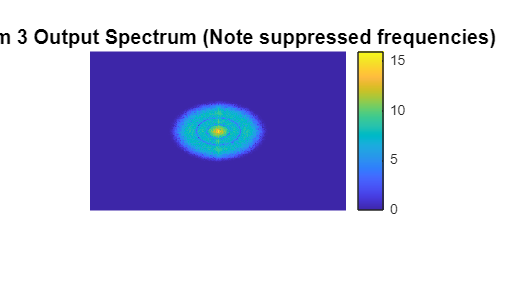


figure('Name', 'System 3 Output Spectrum (Suppressed Frequencies)', 'Position', [950, 950, 600, 500]);
imshow(log(abs(img3_fft) + 1), []);
title('System 3 Output Spectrum (Note suppressed frequencies)', 'FontSize', 12, 'FontWeight', 'bold');
colormap("parula");
colorbar;

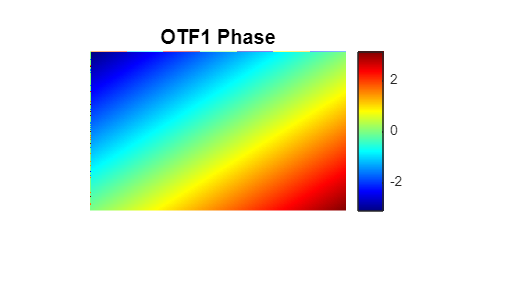


figure('Name', 'OTF1 Phase', 'Position', [100, 50, 600, 500]);
imshow(angle(otf1), []);
title('OTF1 Phase', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

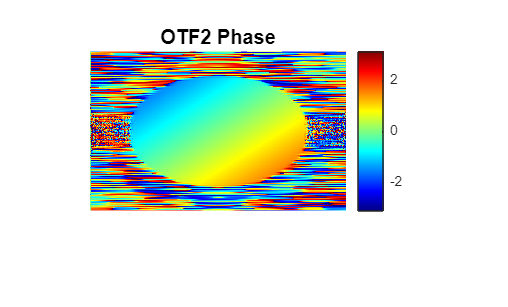


figure('Name', 'OTF2 Phase', 'Position', [150, 100, 600, 500]);
imshow(angle(otf2), []);
title('OTF2 Phase', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

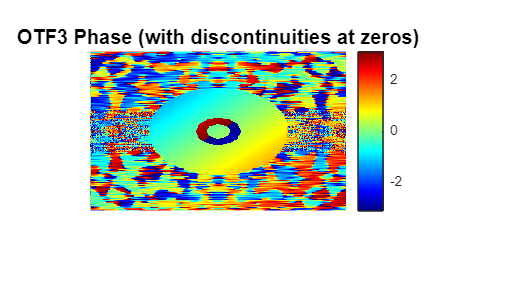


figure('Name', 'OTF3 Phase', 'Position', [200, 150, 600, 500]);
imshow(angle(otf3), []);
title('OTF3 Phase (with discontinuities at zeros)', 'FontSize', 12, 'FontWeight', 'bold');
colormap(jet);
colorbar;

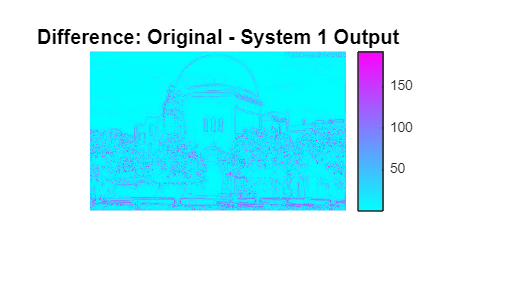


figure('Name', 'Difference: Original - System 1', 'Position', [250, 200, 600, 500]);
diff1 = abs(img - img1_processed);
imshow(diff1, []);
title('Difference: Original - System 1 Output', 'FontSize', 12, 'FontWeight', 'bold');
colormap("cool");
colorbar;

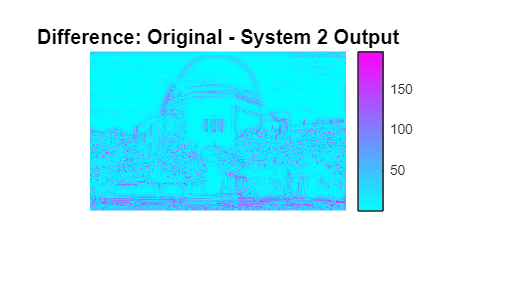


figure('Name', 'Difference: Original - System 2', 'Position', [300, 250, 600, 500]);
diff2 = abs(img - img2_processed);
imshow(diff2, []);
title('Difference: Original - System 2 Output', 'FontSize', 12, 'FontWeight', 'bold');
colormap("cool");
colorbar;

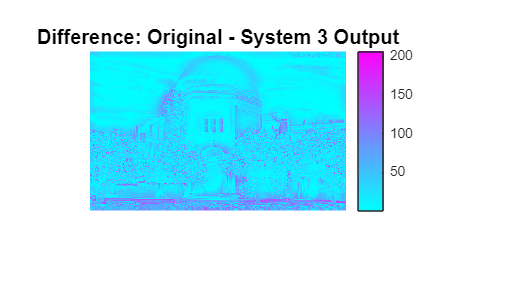


figure('Name', 'Difference: Original - System 3', 'Position', [350, 300, 600, 500]);
diff3 = abs(img - img3_processed);
imshow(diff3, []);
title('Difference: Original - System 3 Output', 'FontSize', 12, 'FontWeight', 'bold');
colormap("cool");
colorbar;


otf3_profile = abs(otf3(center_freq_row, :));
zero_indices = find(otf3_profile < 0.01 * max(otf3_profile));
if ~isempty(zero_indices)
    zero_freqs = fx(zero_indices);
    fprintf('\nOTF3 has near-zero values at frequencies: ');
    fprintf('%.3f ', zero_freqs);
    fprintf(' cycles/pixel\n');
end


OTF3 has near-zero values at frequencies: 

-0.498 -0.495 -0.492 -0.489 -0.486 -0.483 -0.480 -0.477 -0.474 -0.471 -0.468 -0.465 -0.462 -0.459 -0.456 -0.453 -0.450 -0.447 -0.444 -0.441 -0.438 -0.434 -0.431 -0.428 -0.425 -0.422 -0.419 -0.416 -0.413 -0.410 -0.407 -0.404 -0.401 -0.398 -0.395 -0.392 -0.389 -0.386 -0.383 -0.380 -0.377 -0.373 -0.370 -0.367 -0.364 -0.361 -0.358 -0.355 -0.352 -0.349 -0.346 -0.343 -0.340 -0.337 -0.334 -0.331 -0.328 -0.325 -0.322 -0.319 -0.316 -0.312 -0.309 -0.306 -0.303 -0.300 -0.297 -0.294 -0.291 -0.288 -0.285 -0.282 -0.279 -0.276 -0.273 -0.270 -0.267 -0.264 -0.261 -0.258 -0.255 -0.252 -0.248 -0.245 -0.242 -0.239 -0.236 -0.233 -0.230 -0.227 -0.224 -0.221 -0.218 -0.215 -0.212 -0.209 -0.206 -0.203 -0.200 -0.197 -0.194 -0.191 -0.188 -0.184 -0.181 -0.178 -0.175 -0.172 -0.169 -0.166 -0.163 -0.160 -0.157 -0.154 -0.151 -0.084 0.087 0.154 0.157 0.160 0.163 0.166 0.169 0.172 0.175 0.178 0.181 0.184 0.188 0.191 0.194 0.197 0.200 0.203 0.206 0.209 0.212 0.215 0.218 0.221 0.224 0.227 0.230 0.233 0.236 0.239 0.242 0.

 cycles/pixel



mse1 = mean((img(:) - img1_processed(:)).^2);
mse2 = mean((img(:) - img2_processed(:)).^2);
mse3 = mean((img(:) - img3_processed(:)).^2);

fprintf('System 1 MSE: %.6f (Sharp, high contrast, preserves edges)\n', mse1);

System 1 MSE: 692.902803 (Sharp, high contrast, preserves edges)


fprintf('System 2 MSE: %.6f (Moderate blur, good overall quality)\n', mse2);

System 2 MSE: 1092.099259 (Moderate blur, good overall quality)


fprintf('System 3 MSE: %.6f (Heavy blur with artifacts due to OTF zeros)\n', mse3);

System 3 MSE: 1489.264132 (Heavy blur with artifacts due to OTF zeros)


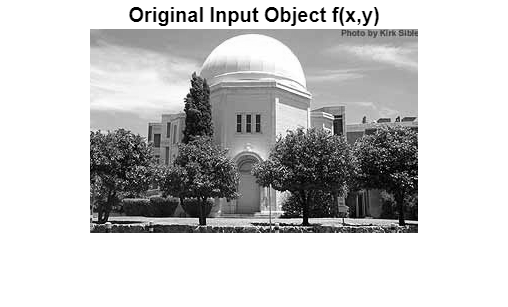

% 2.

% Inverse Filtering: Ideal but unstable near zeros
% Wiener Filtering: Practical with noise regularization
% Constrained Filtering: Acknowledges fundamental limits
% Information destroyed by zeros in OTF cannot be perfectly recovered.


load forclass;
original_img = double(img);
[M, N] = size(original_img);
dx = 1; dy = 1; 
x = (-(N-1)/2:(N-1)/2) * dx;
y = (-(M-1)/2:(M-1)/2) * dy;
[X, Y] = meshgrid(x, y);
sigma1 = 1.5;
psf1 = exp(-(X.^2 + Y.^2)/(2*sigma1^2));
psf1 = psf1/sum(psf1(:));
sigma2 = 4.0;
psf2 = exp(-(X.^2 + Y.^2)/(2*sigma2^2));
psf2 = psf2/sum(psf2(:));
sigma3 = 8.0;
psf3_base = exp(-(X.^2 + Y.^2)/(2*sigma3^2));
k_zero = 0.1;
oscillation = cos(2*pi*k_zero*sqrt(X.^2 + Y.^2));
psf3 = psf3_base .* (0.5 + 0.5*oscillation);
psf3 = psf3/sum(psf3(:));

otf1 = fftshift(fft2(ifftshift(psf1)));
otf2 = fftshift(fft2(ifftshift(psf2)));
otf3 = fftshift(fft2(ifftshift(psf3)));

img_fft = fftshift(fft2(original_img));
img1_fft_degraded = img_fft .* otf1;
img2_fft_degraded = img_fft .* otf2;
img3_fft_degraded = img_fft .* otf3;

img1_degraded = real(ifft2(ifftshift(img1_fft_degraded)));
img2_degraded = real(ifft2(ifftshift(img2_fft_degraded)));
img3_degraded = real(ifft2(ifftshift(img3_fft_degraded)));

figure('Name', 'Original Image', 'Position', [100, 100, 600, 500]);
imshow(original_img, []);
title('Original Input Object f(x,y)', 'FontSize', 12, 'FontWeight', 'bold');

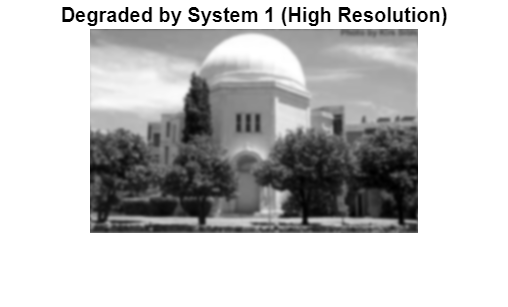


figure('Name', 'Degraded Image - System 1', 'Position', [150, 150, 600, 500]);
imshow(img1_degraded, []);
title('Degraded by System 1 (High Resolution)', 'FontSize', 12, 'FontWeight', 'bold');

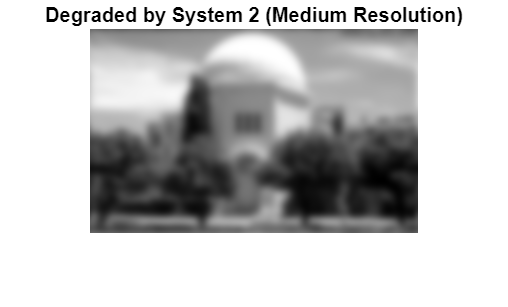


figure('Name', 'Degraded Image - System 2', 'Position', [200, 200, 600, 500]);
imshow(img2_degraded, []);
title('Degraded by System 2 (Medium Resolution)', 'FontSize', 12, 'FontWeight', 'bold');

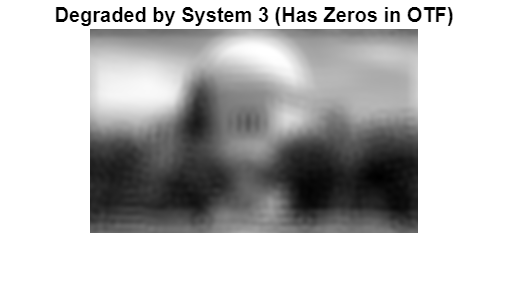


figure('Name', 'Degraded Image - System 3', 'Position', [250, 250, 600, 500]);
imshow(img3_degraded, []);
title('Degraded by System 3 (Has Zeros in OTF)', 'FontSize', 12, 'FontWeight', 'bold');




epsilon = 1e-6;

otf1_inv = 1./(otf1 + epsilon);
otf2_inv = 1./(otf2 + epsilon);
otf3_inv = 1./(otf3 + epsilon);

img1_recovered_ideal = real(ifft2(ifftshift(img1_fft_degraded .* otf1_inv)));
img2_recovered_ideal = real(ifft2(ifftshift(img2_fft_degraded .* otf2_inv)));
img3_recovered_ideal = real(ifft2(ifftshift(img3_fft_degraded .* otf3_inv)));

NSR = 0.01; 
wiener1 = conj(otf1)./(abs(otf1).^2 + NSR);
wiener2 = conj(otf2)./(abs(otf2).^2 + NSR);
wiener3 = conj(otf3)./(abs(otf3).^2 + NSR);

img1_recovered_wiener = real(ifft2(ifftshift(img1_fft_degraded .* wiener1)));
img2_recovered_wiener = real(ifft2(ifftshift(img2_fft_degraded .* wiener2)));
img3_recovered_wiener = real(ifft2(ifftshift(img3_fft_degraded .* wiener3)));

otf3_magnitude = abs(otf3);
zero_threshold = 0.01 * max(otf3_magnitude(:));
zero_mask = otf3_magnitude < zero_threshold;

fprintf('Percentage of frequencies with near-zero OTF: %.2f%%\n', ...
    100 * sum(zero_mask(:)) / numel(zero_mask));

Percentage of frequencies with near-zero OTF: 92.92%


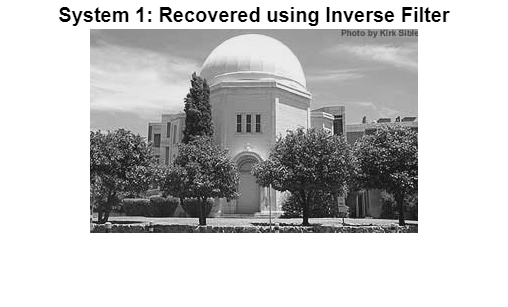


otf3_inv_constrained = zeros(size(otf3));
non_zero_mask = ~zero_mask;
otf3_inv_constrained(non_zero_mask) = 1./otf3(non_zero_mask);
img3_recovered_constrained = real(ifft2(ifftshift(img3_fft_degraded .* otf3_inv_constrained)));

figure('Name', 'System 1 - Inverse Filter Recovery', 'Position', [300, 300, 600, 500]);
imshow(img1_recovered_ideal, []);
title('System 1: Recovered using Inverse Filter', 'FontSize', 12, 'FontWeight', 'bold');

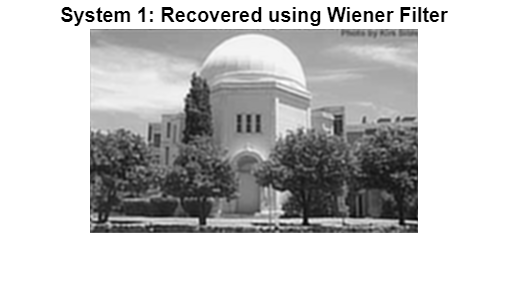


figure('Name', 'System 1 - Wiener Filter Recovery', 'Position', [350, 350, 600, 500]);
imshow(img1_recovered_wiener, []);
title('System 1: Recovered using Wiener Filter', 'FontSize', 12, 'FontWeight', 'bold');

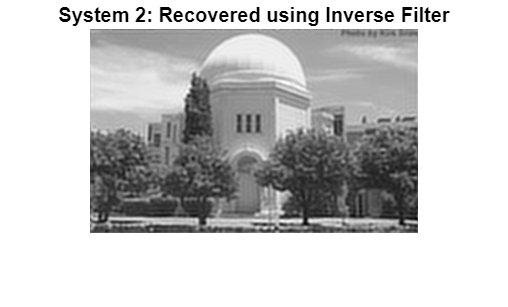


figure('Name', 'System 2 - Inverse Filter Recovery', 'Position', [400, 400, 600, 500]);
imshow(img2_recovered_ideal, []);
title('System 2: Recovered using Inverse Filter', 'FontSize', 12, 'FontWeight', 'bold');

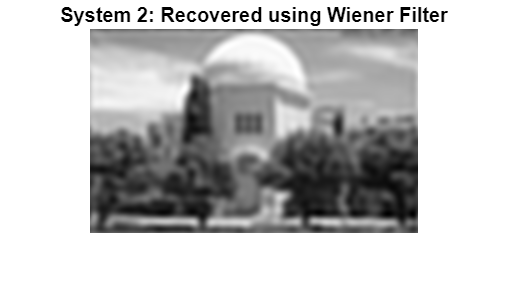


figure('Name', 'System 2 - Wiener Filter Recovery', 'Position', [450, 450, 600, 500]);
imshow(img2_recovered_wiener, []);
title('System 2: Recovered using Wiener Filter', 'FontSize', 12, 'FontWeight', 'bold');

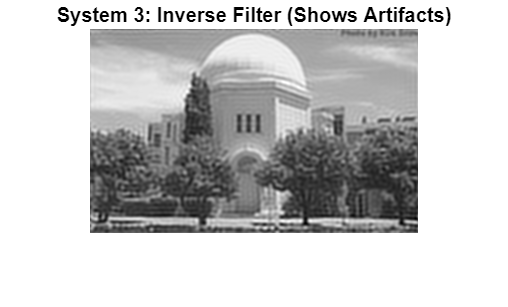


figure('Name', 'System 3 - Inverse Filter Recovery (Problematic)', 'Position', [500, 500, 600, 500]);
imshow(img3_recovered_ideal, []);
title('System 3: Inverse Filter (Shows Artifacts)', 'FontSize', 12, 'FontWeight', 'bold');

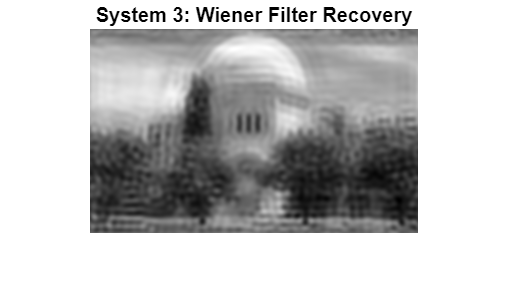


figure('Name', 'System 3 - Wiener Filter Recovery', 'Position', [550, 550, 600, 500]);
imshow(img3_recovered_wiener, []);
title('System 3: Wiener Filter Recovery', 'FontSize', 12, 'FontWeight', 'bold');

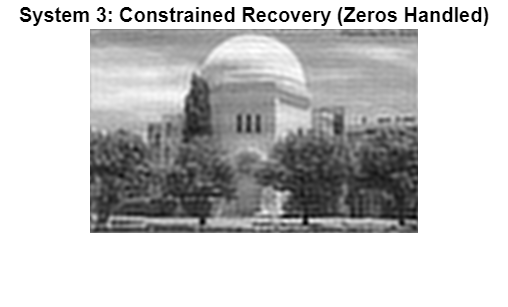


figure('Name', 'System 3 - Constrained Recovery', 'Position', [600, 600, 600, 500]);
imshow(img3_recovered_constrained, []);
title('System 3: Constrained Recovery (Zeros Handled)', 'FontSize', 12, 'FontWeight', 'bold');

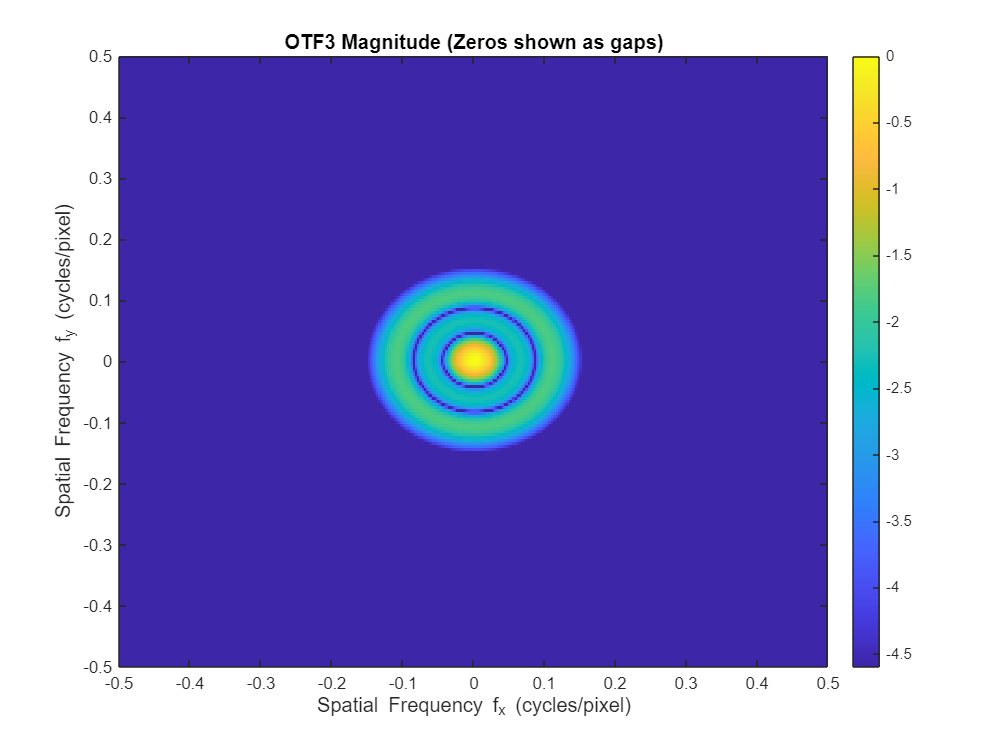


fx = (-(N-1)/2:(N-1)/2) / (N*dx);
fy = (-(M-1)/2:(M-1)/2) / (M*dy);

figure('Name', 'OTF3 Magnitude with Zero Locations', 'Position', [650, 650, 800, 600]);
otf3_mag_display = abs(otf3);
otf3_mag_display(zero_mask) = NaN; 
imagesc(fx, fy, log(otf3_mag_display + 1e-10));
title('OTF3 Magnitude (Zeros shown as gaps)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Spatial Frequency f_x (cycles/pixel)', 'FontSize', 12);
ylabel('Spatial Frequency f_y (cycles/pixel)', 'FontSize', 12);
colormap("parula");
colorbar;
axis xy;


mse_original = @(recovered) mean((original_img(:) - recovered(:)).^2);

mse1_inverse = mse_original(img1_recovered_ideal);
mse1_wiener = mse_original(img1_recovered_wiener);

mse2_inverse = mse_original(img2_recovered_ideal);
mse2_wiener = mse_original(img2_recovered_wiener);

mse3_inverse = mse_original(img3_recovered_ideal);
mse3_wiener = mse_original(img3_recovered_wiener);
mse3_constrained = mse_original(img3_recovered_constrained);

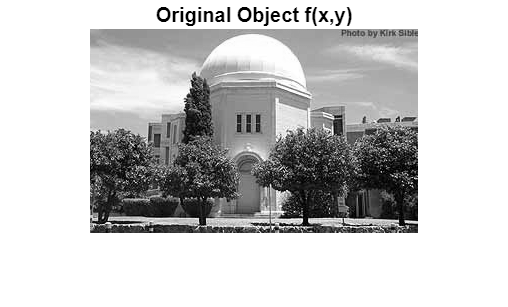

% 3.

% Inverse filtering is hopeless with any noise, even small amounts cause catastrophic amplification
% Wiener filtering is essential for real systems, provides the crucial noise regularization

load forclass; 
original_img = double(img);
[M, N] = size(original_img);
noise_factors = [5, 10, 20, 50];
selected_noise_factor = 20; 
dx = 1; dy = 1; 
x = (-(N-1)/2:(N-1)/2) * dx;
y = (-(M-1)/2:(M-1)/2) * dy;
[X, Y] = meshgrid(x, y);
sigma1 = 1.5;
psf1 = exp(-(X.^2 + Y.^2)/(2*sigma1^2));
psf1 = psf1/sum(psf1(:));
sigma2 = 4.0;
psf2 = exp(-(X.^2 + Y.^2)/(2*sigma2^2));
psf2 = psf2/sum(psf2(:));
sigma3 = 8.0;
psf3_base = exp(-(X.^2 + Y.^2)/(2*sigma3^2));
k_zero = 0.1;
oscillation = cos(2*pi*k_zero*sqrt(X.^2 + Y.^2));
psf3 = psf3_base .* (0.5 + 0.5*oscillation);
psf3 = psf3/sum(psf3(:));

otf1 = fftshift(fft2(ifftshift(psf1)));
otf2 = fftshift(fft2(ifftshift(psf2)));
otf3 = fftshift(fft2(ifftshift(psf3)));

img_fft = fftshift(fft2(original_img));
img1_fft_clean = img_fft .* otf1;
img2_fft_clean = img_fft .* otf2;
img3_fft_clean = img_fft .* otf3;
img1_clean = real(ifft2(ifftshift(img1_fft_clean)));
img2_clean = real(ifft2(ifftshift(img2_fft_clean)));
img3_clean = real(ifft2(ifftshift(img3_fft_clean)));

rng(42); 

noise1 = randn(size(img1_clean)) * selected_noise_factor;
noise2 = randn(size(img2_clean)) * selected_noise_factor;
noise3 = randn(size(img3_clean)) * selected_noise_factor;

img1_noisy = img1_clean + noise1;
img2_noisy = img2_clean + noise2;
img3_noisy = img3_clean + noise3;

figure('Name', 'Original Image', 'Position', [50, 50, 600, 500]);
imshow(original_img, []);
title('Original Object f(x,y)', 'FontSize', 12, 'FontWeight', 'bold');

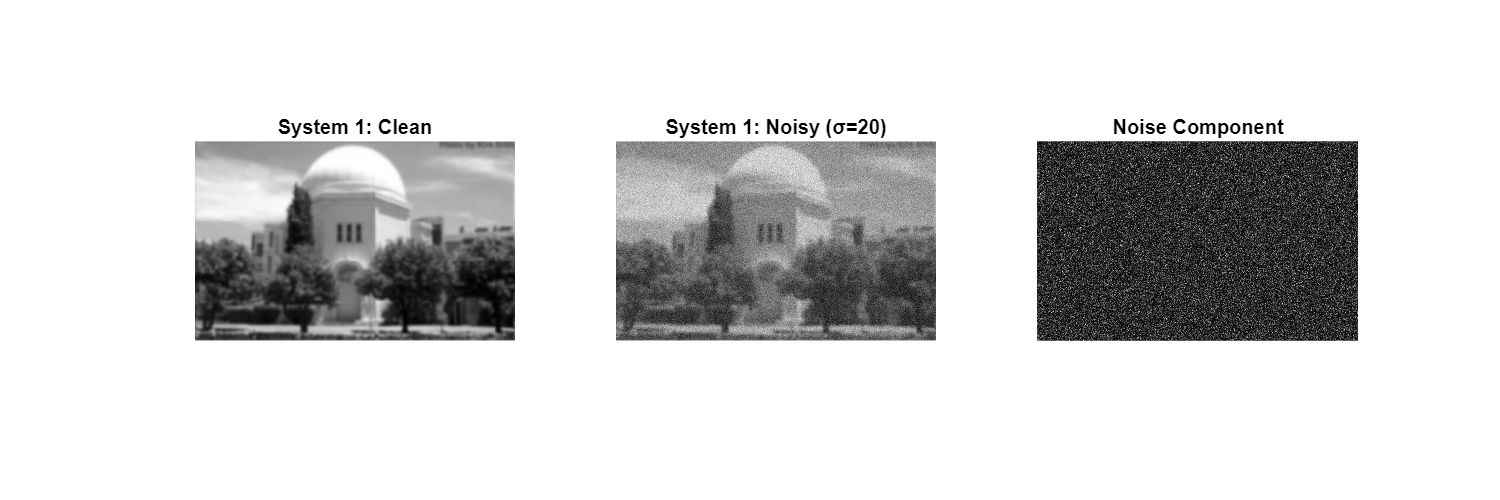


figure('Name', 'System 1 - Clean vs Noisy', 'Position', [100, 100, 1200, 400]);
subplot(1,3,1); imshow(img1_clean, []); title('System 1: Clean', 'FontSize', 12);
subplot(1,3,2); imshow(img1_noisy, []); title(['System 1: Noisy (σ=' num2str(selected_noise_factor) ')'], 'FontSize', 12);
subplot(1,3,3); imshow(abs(img1_noisy - img1_clean), []); title('Noise Component', 'FontSize', 12);

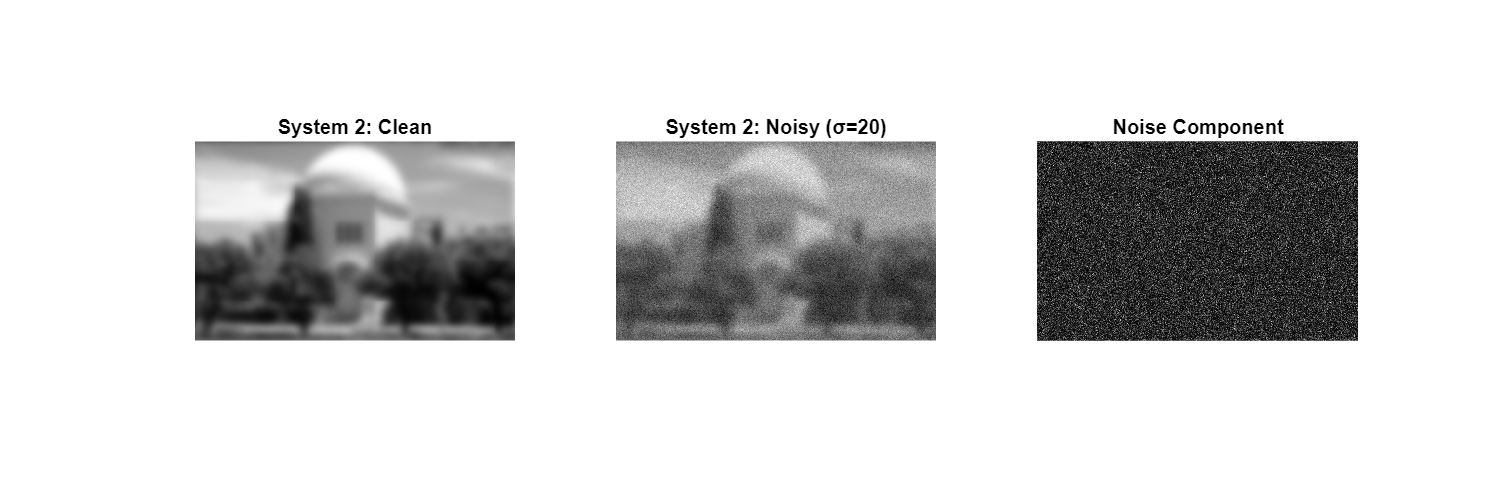


figure('Name', 'System 2 - Clean vs Noisy', 'Position', [150, 150, 1200, 400]);
subplot(1,3,1); imshow(img2_clean, []); title('System 2: Clean', 'FontSize', 12);
subplot(1,3,2); imshow(img2_noisy, []); title(['System 2: Noisy (σ=' num2str(selected_noise_factor) ')'], 'FontSize', 12);
subplot(1,3,3); imshow(abs(img2_noisy - img2_clean), []); title('Noise Component', 'FontSize', 12);

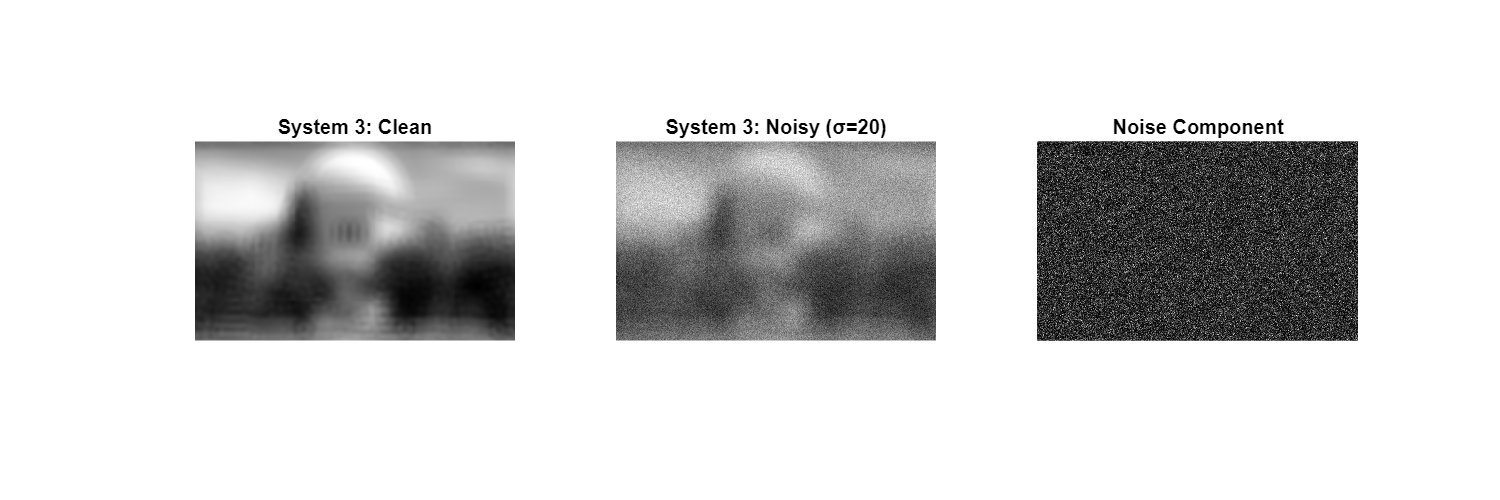


figure('Name', 'System 3 - Clean vs Noisy', 'Position', [200, 200, 1200, 400]);
subplot(1,3,1); imshow(img3_clean, []); title('System 3: Clean', 'FontSize', 12);
subplot(1,3,2); imshow(img3_noisy, []); title(['System 3: Noisy (σ=' num2str(selected_noise_factor) ')'], 'FontSize', 12);
subplot(1,3,3); imshow(abs(img3_noisy - img3_clean), []); title('Noise Component', 'FontSize', 12);


img1_noisy_fft = fftshift(fft2(img1_noisy));
img2_noisy_fft = fftshift(fft2(img2_noisy));
img3_noisy_fft = fftshift(fft2(img3_noisy));
epsilon = 1e-8;
otf1_inv = 1./(otf1 + epsilon);
otf2_inv = 1./(otf2 + epsilon);
otf3_inv = 1./(otf3 + epsilon);

img1_recovered_inverse = real(ifft2(ifftshift(img1_noisy_fft .* otf1_inv)));
img2_recovered_inverse = real(ifft2(ifftshift(img2_noisy_fft .* otf2_inv)));
img3_recovered_inverse = real(ifft2(ifftshift(img3_noisy_fft .* otf3_inv)));

NSR_values = [0.001, 0.01, 0.1, 1.0];
NSR_primary = 0.1;

wiener1 = conj(otf1)./(abs(otf1).^2 + NSR_primary);
wiener2 = conj(otf2)./(abs(otf2).^2 + NSR_primary);
wiener3 = conj(otf3)./(abs(otf3).^2 + NSR_primary);

img1_recovered_wiener = real(ifft2(ifftshift(img1_noisy_fft .* wiener1)));
img2_recovered_wiener = real(ifft2(ifftshift(img2_noisy_fft .* wiener2)));
img3_recovered_wiener = real(ifft2(ifftshift(img3_noisy_fft .* wiener3)));

[gx, gy] = gradient(img1_noisy);
noise_estimate1 = std([gx(:); gy(:)]);
estimated_NSR1 = (noise_estimate1^2) / var(img1_clean(:));

[gx, gy] = gradient(img2_noisy);
noise_estimate2 = std([gx(:); gy(:)]);
estimated_NSR2 = (noise_estimate2^2) / var(img2_clean(:));

[gx, gy] = gradient(img3_noisy);
noise_estimate3 = std([gx(:); gy(:)]);
estimated_NSR3 = (noise_estimate3^2) / var(img3_clean(:));

fprintf('  System 1: %.4f\n', estimated_NSR1);

  System 1: 0.0574


fprintf('  System 2: %.4f\n', estimated_NSR2);

  System 2: 0.0552


fprintf('  System 3: %.4f\n', estimated_NSR3);

  System 3: 0.0613


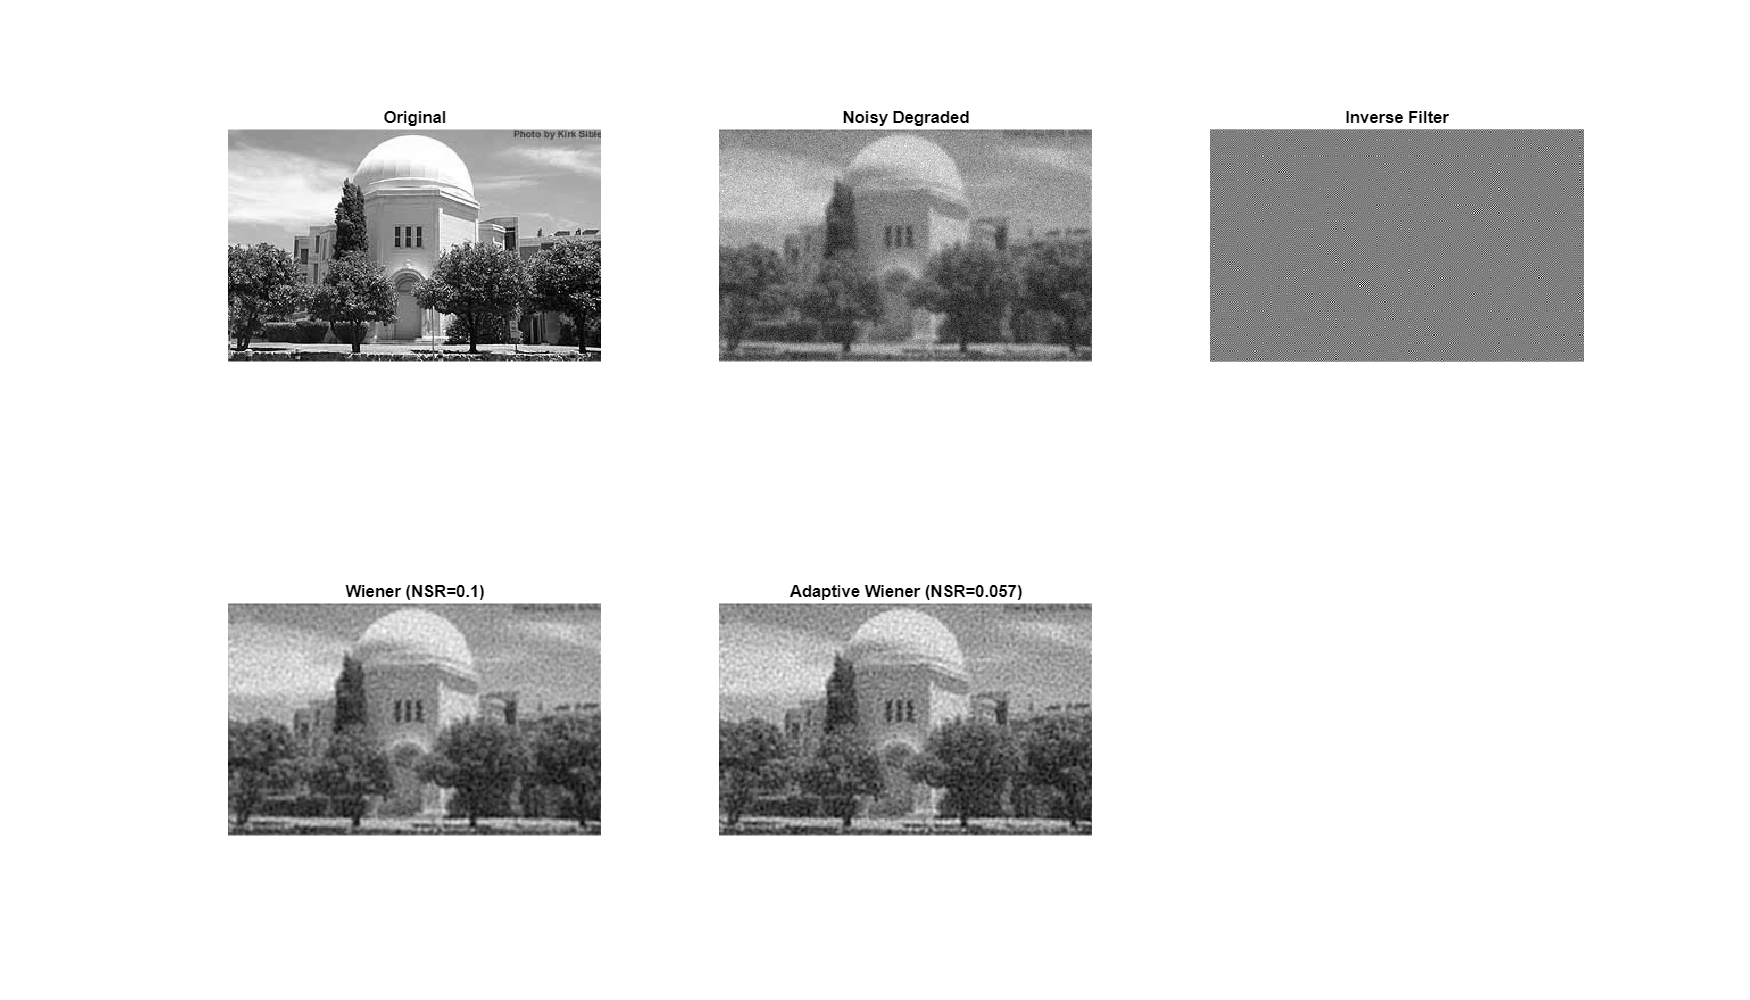


wiener1_adaptive = conj(otf1)./(abs(otf1).^2 + estimated_NSR1);
wiener2_adaptive = conj(otf2)./(abs(otf2).^2 + estimated_NSR2);
wiener3_adaptive = conj(otf3)./(abs(otf3).^2 + estimated_NSR3);

img1_recovered_adaptive = real(ifft2(ifftshift(img1_noisy_fft .* wiener1_adaptive)));
img2_recovered_adaptive = real(ifft2(ifftshift(img2_noisy_fft .* wiener2_adaptive)));
img3_recovered_adaptive = real(ifft2(ifftshift(img3_noisy_fft .* wiener3_adaptive)));

figure('Name', 'System 1 - Deconvolution Results', 'Position', [250, 250, 1400, 800]);
subplot(2,3,1); imshow(original_img, []); title('Original', 'FontSize', 10);
subplot(2,3,2); imshow(img1_noisy, []); title('Noisy Degraded', 'FontSize', 10);
subplot(2,3,3); imshow(img1_recovered_inverse, []); title('Inverse Filter', 'FontSize', 10);
subplot(2,3,4); imshow(img1_recovered_wiener, []); title(['Wiener (NSR=' num2str(NSR_primary) ')'], 'FontSize', 10);
subplot(2,3,5); imshow(img1_recovered_adaptive, []); title(['Adaptive Wiener (NSR=' num2str(estimated_NSR1, '%.3f') ')'], 'FontSize', 10);

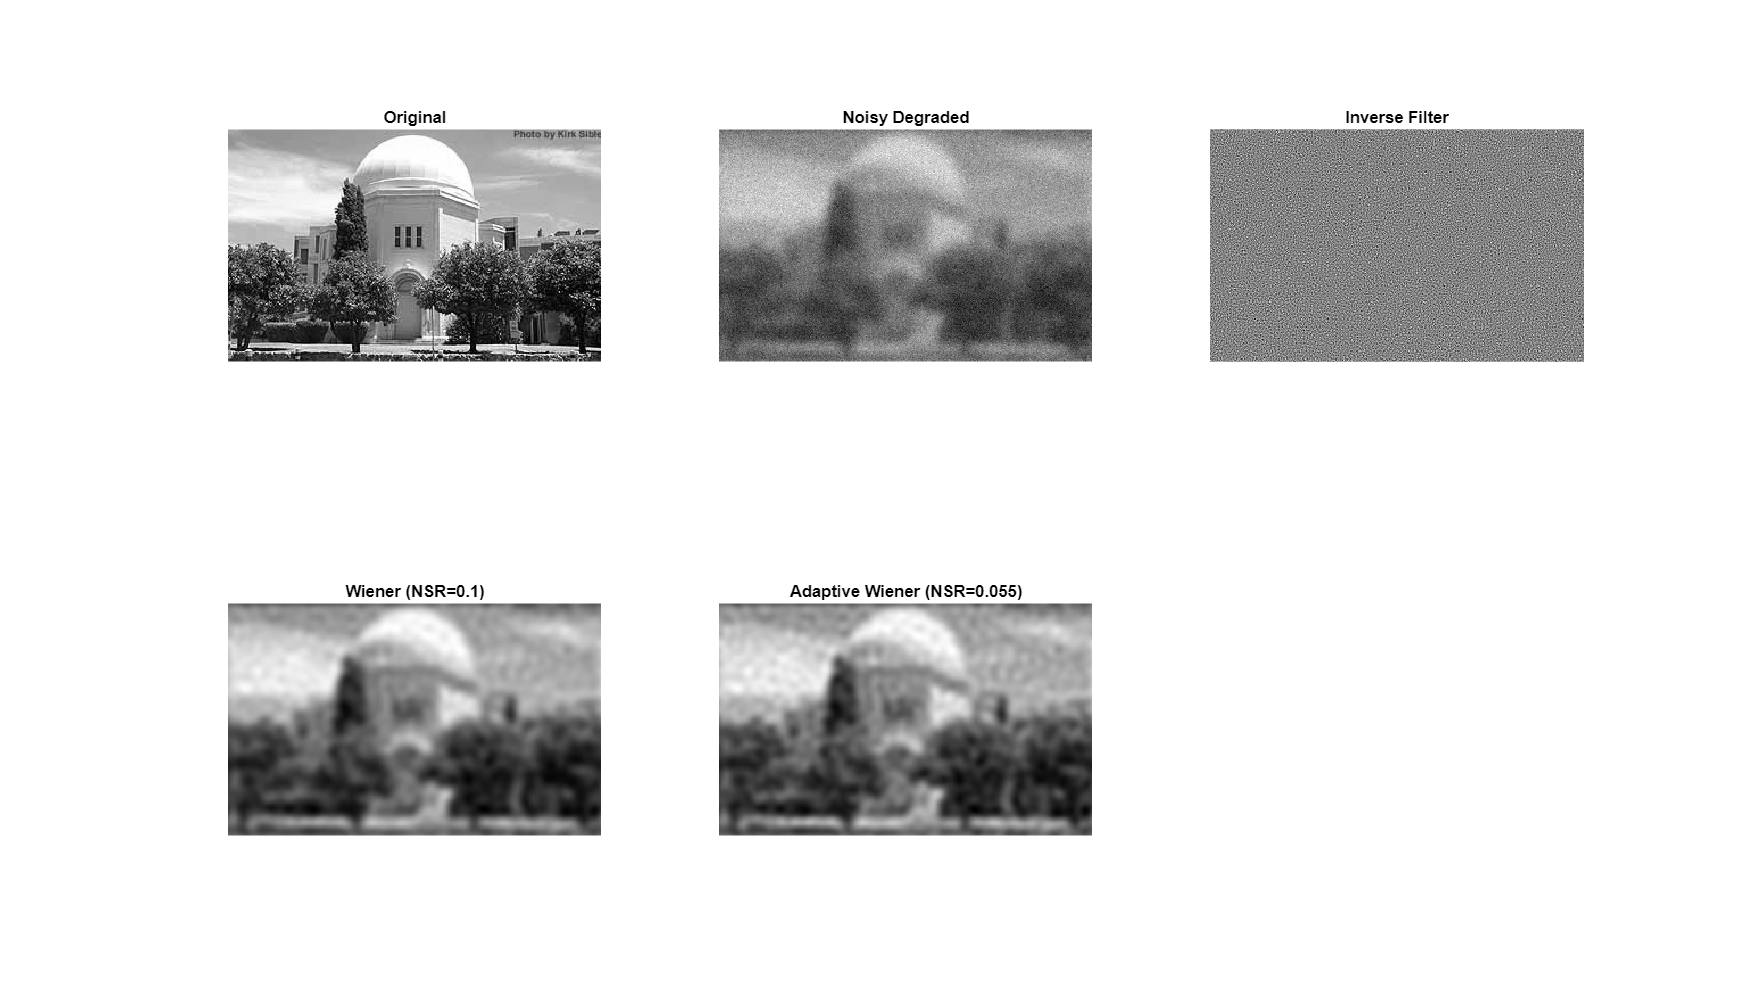


figure('Name', 'System 2 - Deconvolution Results', 'Position', [300, 300, 1400, 800]);
subplot(2,3,1); imshow(original_img, []); title('Original', 'FontSize', 10);
subplot(2,3,2); imshow(img2_noisy, []); title('Noisy Degraded', 'FontSize', 10);
subplot(2,3,3); imshow(img2_recovered_inverse, []); title('Inverse Filter', 'FontSize', 10);
subplot(2,3,4); imshow(img2_recovered_wiener, []); title(['Wiener (NSR=' num2str(NSR_primary) ')'], 'FontSize', 10);
subplot(2,3,5); imshow(img2_recovered_adaptive, []); title(['Adaptive Wiener (NSR=' num2str(estimated_NSR2, '%.3f') ')'], 'FontSize', 10);

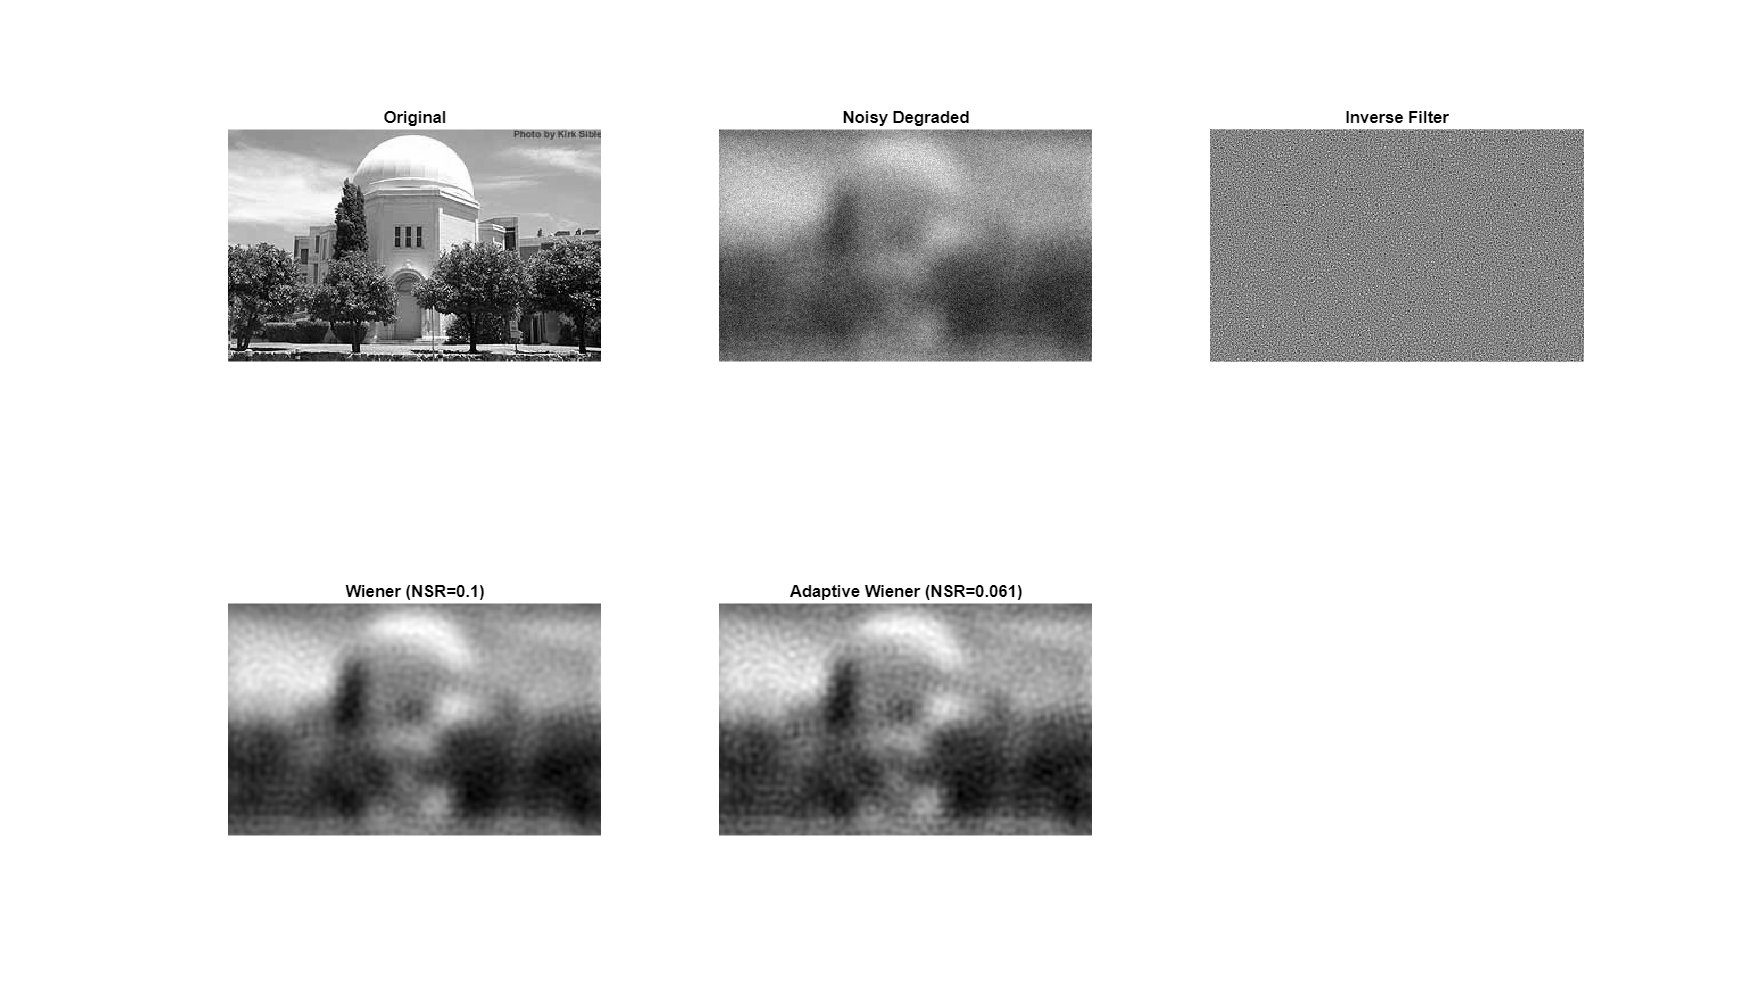


figure('Name', 'System 3 - Deconvolution Results', 'Position', [350, 350, 1400, 800]);
subplot(2,3,1); imshow(original_img, []); title('Original', 'FontSize', 10);
subplot(2,3,2); imshow(img3_noisy, []); title('Noisy Degraded', 'FontSize', 10);
subplot(2,3,3); imshow(img3_recovered_inverse, []); title('Inverse Filter', 'FontSize', 10);
subplot(2,3,4); imshow(img3_recovered_wiener, []); title(['Wiener (NSR=' num2str(NSR_primary) ')'], 'FontSize', 10);
subplot(2,3,5); imshow(img3_recovered_adaptive, []); title(['Adaptive Wiener (NSR=' num2str(estimated_NSR3, '%.3f') ')'], 'FontSize', 10);



mse_calc = @(recovered) mean((original_img(:) - recovered(:)).^2);

mse_results = struct();
systems = {'System1', 'System2', 'System3'};
recovered_images = {
    {img1_recovered_inverse, img1_recovered_wiener, img1_recovered_adaptive};
    {img2_recovered_inverse, img2_recovered_wiener, img2_recovered_adaptive};
    {img3_recovered_inverse, img3_recovered_wiener, img3_recovered_adaptive}
};
method_names = {'Inverse', 'Wiener', 'Adaptive'};

for s = 1:3
    for m = 1:3
        mse_results.(systems{s}).(method_names{m}) = mse_calc(recovered_images{s}{m});
    end
end

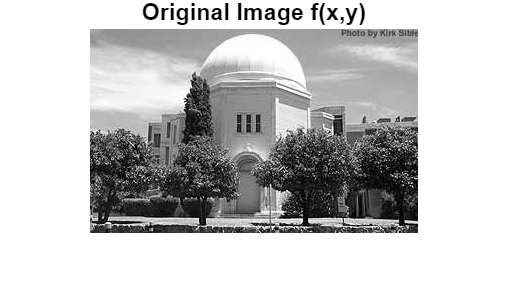

% Image Processing


% 1.

% Low‐pass filter H_low retains frequencies within radius ≤ cutoff,
% yielding a blurred image by removing fine details.
% High‐pass filter H_high retains frequencies ≥ cutoff,
% emphasizing edges and high‐frequency content.
% Vertical edges correspond to horizontal intensity gradients.
% The vertical kernel approximates ∂/∂x, highlighting vertical edges.

load forclass;          
f = im2double(img);     
figure; imshow(f, []);
title('Original Image f(x,y)', 'FontSize', 14, 'FontWeight', 'bold');

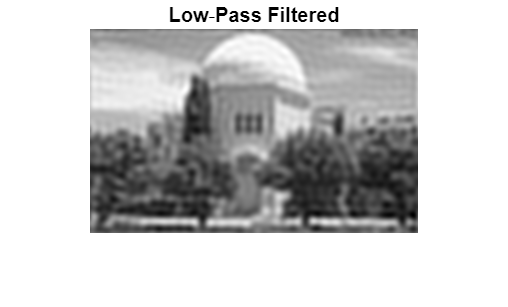

[M, N] = size(f);
dx = 1; dy = 1;
fx = (-(N-1)/2:(N-1)/2)/(N*dx);
fy = (-(M-1)/2:(M-1)/2)/(M*dy);
[Fx, Fy] = meshgrid(fx, fy);

cutoff = 0.1;
H_low  = double(sqrt(Fx.^2 + Fy.^2) <= cutoff);
H_high = double(sqrt(Fx.^2 + Fy.^2) >= cutoff);
F = fftshift(fft2(f));
F_low  = F .* H_low;
F_high = F .* H_high;
f_low  = real(ifft2(ifftshift(F_low)));
f_high = real(ifft2(ifftshift(F_high)));
sobel_vert = [1  0 -1; 2 0 -2; 1 0 -1] / 8;
edges_vert = imfilter(f, sobel_vert, 'replicate');

figure; imshow(f_low, []);
title('Low‐Pass Filtered', 'FontSize', 12);

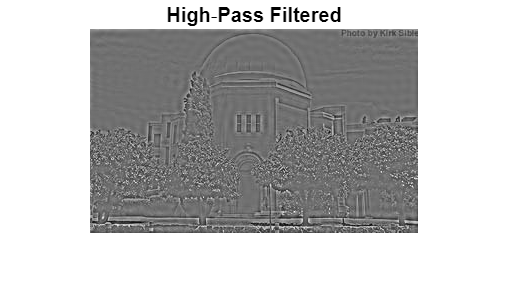


figure; imshow(f_high, []);
title('High‐Pass Filtered', 'FontSize', 12);

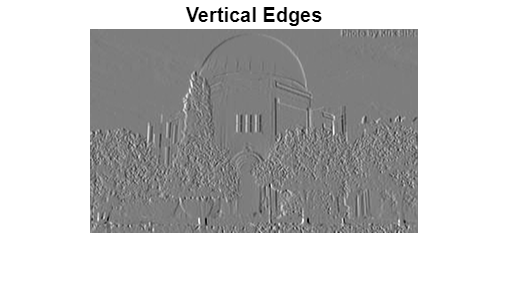


figure; imshow(edges_vert, []);
title('Vertical Edges', 'FontSize', 12);

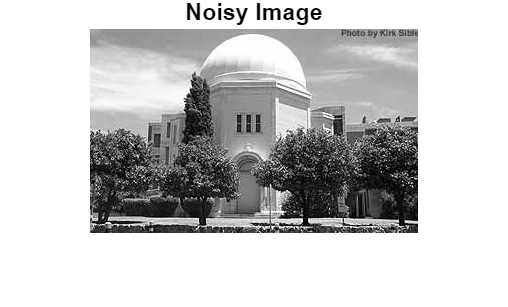

% 2.

% A 3×3 window is centered at each pixel.  
% The neighborhood values are collected into a vector.  
% MATLAB’s median() function finds the median value.  
% That median replaces the central pixel, removing impulse noise  
% while preserving edges better than linear filtering.  

load forclass;      
f_noisy = im2double(img);
[M, N] = size(f_noisy);
figure; imshow(f_noisy, []);
title('Noisy Image', 'FontSize',14, 'FontWeight','bold');

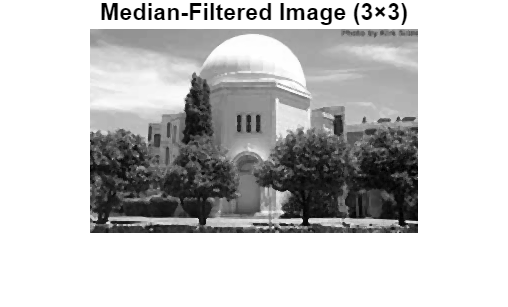

w = 3;                  
pad = floor(w/2);
f_padded = padarray(f_noisy, [pad pad], 'replicate');
f_med = zeros(M, N);

for i = 1:M
    for j = 1:N
       
        block = f_padded(i:(i+2*pad), j:(j+2*pad));
        m = median(block(:));
        f_med(i, j) = m;
    end
end

figure; imshow(f_med, []);
title('Median-Filtered Image (3×3)', 'FontSize',14, 'FontWeight','bold');

% 3.

% Opening (erode then dilate) with a disk removes small artifacts.
% Hole filling ensures each tree region is solid.
% Closing (dilate then erode) smooths jagged edges of the regions.

load forclass;       
I = im2double(img);
figure; imshow(I, []);
title('Original Image f(x,y)','FontSize',14,'FontWeight','bold');

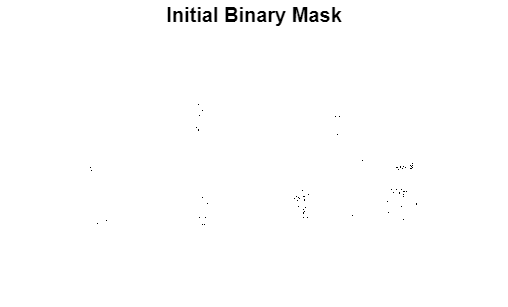

level = graythresh(I);  
BW = I > level;
figure; imshow(BW);
title('Initial Binary Mask','FontSize',12);

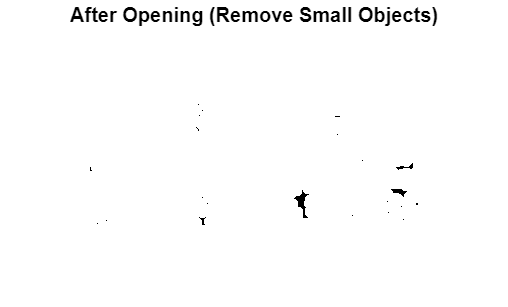

se = strel('disk',5);
BW_open = imopen(BW, se);
figure; imshow(BW_open);
title('After Opening (Remove Small Objects)','FontSize',12);

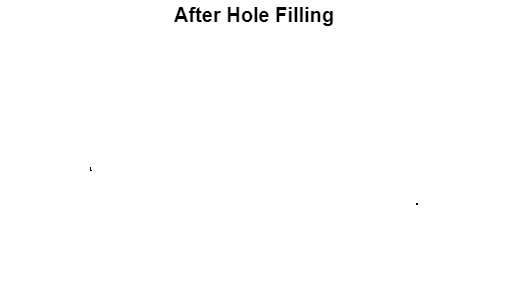

BW_filled = imfill(BW_open, 'holes');
figure; imshow(BW_filled);
title('After Hole Filling','FontSize',12);

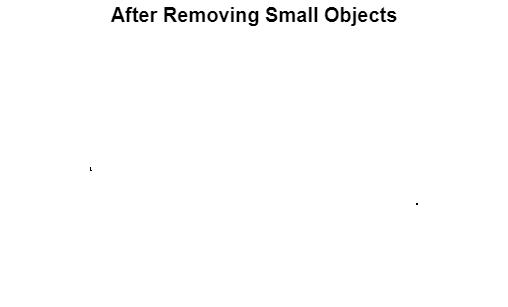

BW_clean = bwareaopen(BW_filled, 500);
figure; imshow(BW_clean);
title('After Removing Small Objects','FontSize',12);

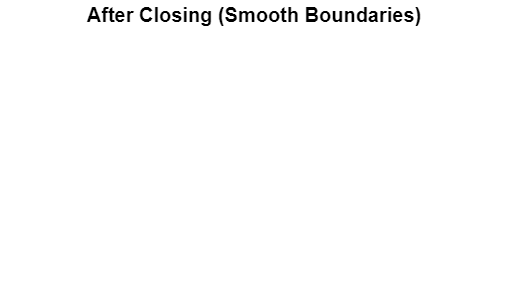

BW_smooth = imclose(BW_clean, strel('disk',3));
figure; imshow(BW_smooth);
title('After Closing (Smooth Boundaries)','FontSize',12);

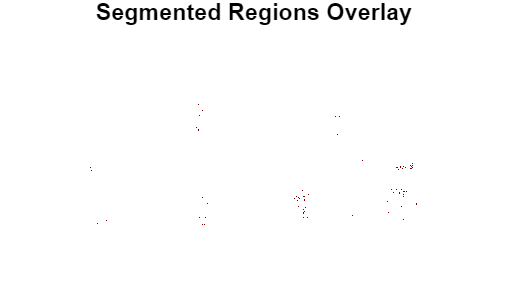

RGB = cat(3, I, I, I);
RGB(:,:,1) = RGB(:,:,1) + 0.5 * BW_smooth; 
figure; imshow(RGB);
title('Segmented Regions Overlay','FontSize',14,'FontWeight','bold');